## Lab 2

Thomas Conaway

Lab Partners: Jeff, Avis

## Problem 1

A) The probability distribution of the background changes as we integrate (sum) for more days.

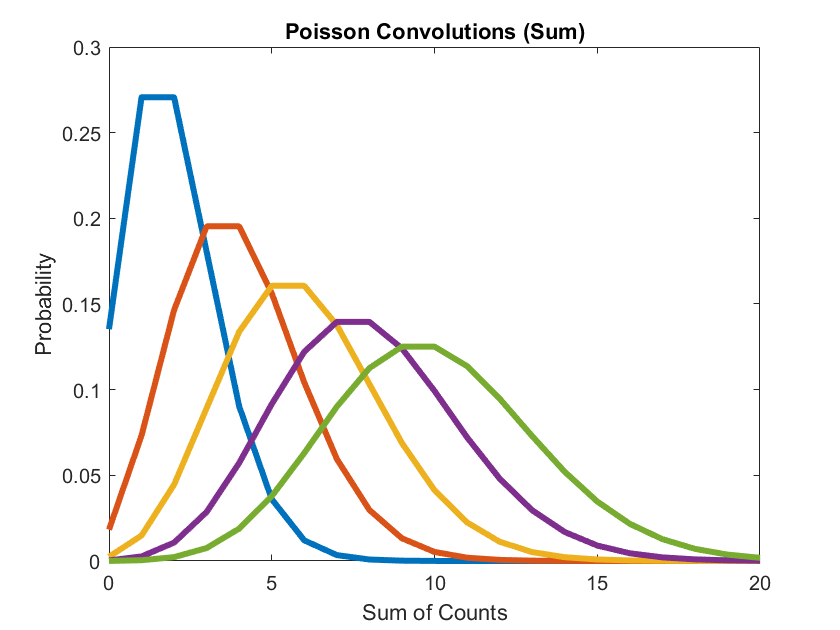

clc; clear; close all;
X = 2; % average cosmic-ray background in 1 day
Y = 7; % average number of gamma-rays emitted by hypothetical source
onedaypoisson = makedist("Poisson","lambda",X);
xaxis = 0:1:20;
pdfoneday = pdf(onedaypoisson,xaxis); % quantized pdf
pdfoneday = pdfoneday/sum(pdfoneday); % normalized pdf
plot(xaxis,pdfoneday,"LineWidth",3); % if plotting stairs then shift half interval
hold on;
% plotting convolutions
pdftwoday = conv(pdfoneday,pdfoneday);
plot(0:length(pdftwoday)-1,pdftwoday,"LineWidth",3);
pdfthreeday = conv(pdftwoday,pdfoneday);
plot(0:length(pdfthreeday)-1,pdfthreeday,"LineWidth",3);
pdffourday = conv(pdfthreeday,pdfoneday);
plot(0:length(pdffourday)-1,pdffourday,"LineWidth",3);
pdffiveday = conv(pdffourday,pdfoneday);
plot(0:length(pdffiveday)-1,pdffiveday,"LineWidth",3);
xlim ([0,20]);
xlabel("Sum of Counts")
ylabel("Probability");
title("Poisson Convolutions (Sum)");
hold off;

B) After 5 days, the summed probability distribution is still a Poisson distribution.

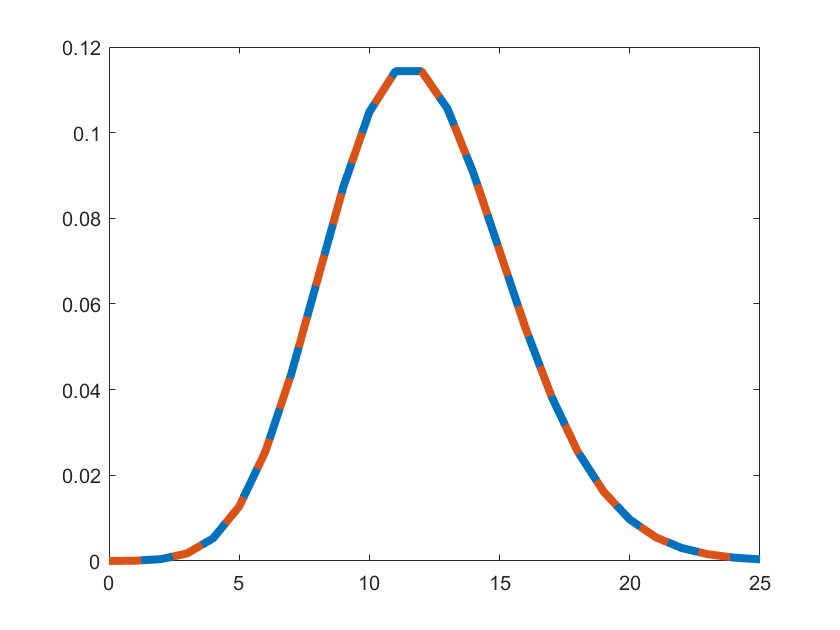

pdfsixday = conv(pdffiveday,pdfoneday);
plot(0:length(pdfsixday)-1,pdfsixday,"LineWidth",4);
xlim([0,25]);
hold on;
mean = dot(pdfsixday,0:length(pdfsixday)-1);
sixdaytest = makedist("Poisson","lambda",mean);
plot(0:length(pdfsixday)-1,pdf(sixdaytest,0:length(pdfsixday)-1),"LineStyle","--","LineWidth",4);
hold off;

The Poisson distibution tells us the probability of having a certain number of independent events occur within an interval, and is centered about the average number of events. When we sum random independent variables we can use the mathematical definition of the convolution to produce the distribution for their sum. The sum of independent variables is independent, so sum distribution also takes the form of a Poisson centered at a new mean.

C) Evolution of the probability distribution as we average days.

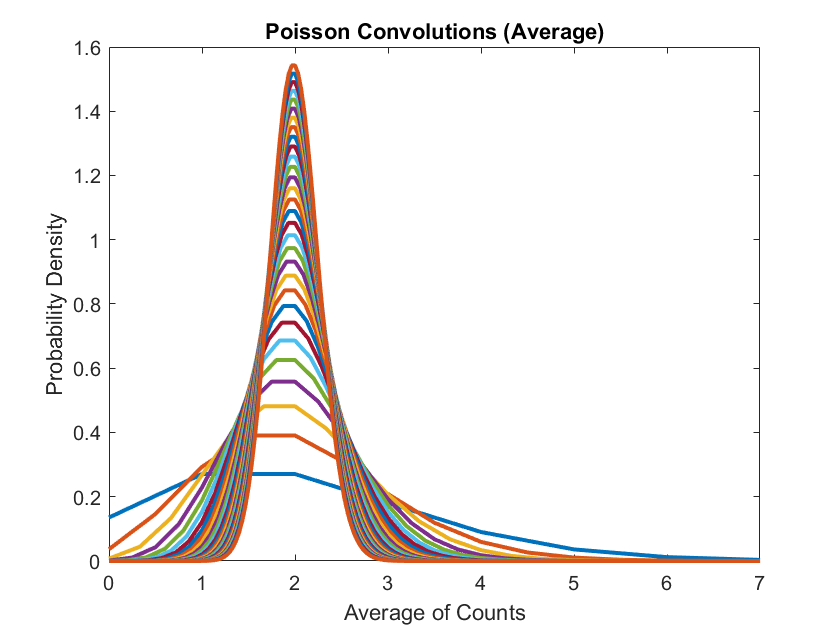

% Scaling just the x-axis gives the probability mass function for the
% average. I've normalized the area for these plots by scaling the y-axis
% (now giving discrete probability density) to demonstrate how the shape of the
% distribution evolves.
plot(xaxis,pdfoneday,"LineWidth",2);
hold on;
plot((0:length(pdftwoday)-1)/2.0,pdftwoday*2,"LineWidth",2);
plot((0:length(pdfthreeday)-1)/3.0,pdfthreeday*3,"LineWidth",2);
plot((0:length(pdffourday)-1)/4.0,pdffourday*4,"LineWidth",2);
plot((0:length(pdffiveday)-1)/5.0,pdffiveday*5,"LineWidth",2);
plot((0:length(pdfsixday)-1)/6.0,pdfsixday*6,"LineWidth",2);
pdfold = pdfsixday;
for x = 7:30 % loop to generate plots for more convolutions
    pdfnew = conv(pdfoneday,pdfold);
    plot((0:length(pdfnew)-1)/x,pdfnew*x,"LineWidth",2);
    pdfold = pdfnew;
end
% quick check for the area under the distribution
% trapz(xaxis,pdfoneday)
% trapz((0:length(pdffiveday)-1)/5.0,pdffiveday*5)
xlim([0,7]);
xlabel("Average of Counts");
ylabel("Probability Density");
title("Poisson Convolutions (Average)");

As the number of days grows larger, the distribution pulls in and becomes more sharply peaked at the mean. In B) the sum distribution was still a Poisson distribution as it spread out and the mean moved to the right, but because the Poisson distribution approximates a Gaussian for very large means then as our mean increases with each convolution the distribution becomes more Gaussian. The central limit theorem says that the distribution for the sums or means of many samples of random independent observations will approximate a Gaussian distribution. We see that graphically here that the sum and average distributions become more Gaussian the more times we perform a convolution.

D) Calculating the 'sigma' of our observation.

% CHECK if we use sum or average here. The examples used have typically
% been dice rolls. Since we're being given a sum (total gamma-rays) so it feels like
% we should use the sum distribution.

N = 5; % number of days
Y % average number of gamma-rays per day from source

Y = 7

rays = Y*N % total number of gamma-rays seen from source

rays = 35

% finding mean of the PMF
mean5 = dot(pdffiveday,(0:length(pdffiveday)-1)) % same mean as the sum of 5 convolution

mean5 = 10.0000

% creating poisson distribution with same mean as day 5
pdf5test = makedist("Poisson","lambda",mean5);
prob = cdf(pdf5test,rays,'upper');
disp(prob);

   1.6667e-10



sigma = abs(norminv(prob));
disp(sigma);

    6.2824



## Problem 2

Examining an observed interval background which follows a skewed continuous Rayleigh distribution.

A) Showing how the distribution changes when averaged over more observing intervals.

clc; clear; close all;
dist = makedist("Rayleigh","b",10);
x = 0:50;
pdfray = pdf(dist,x);
sum(pdfray) % THIS was a problem

ans = 0.9992

pdfray = pdfray/sum(pdfray); % normalize
sum(pdfray)

ans = 1.0000

plot(x,pdfray);
hold on;
pdfold = pdfray

pdfold =          0    0.0100    0.0196    0.0287    0.0370    0.0442    0.0502    0.0548    0.0581    0.0601    0.0607    0.0601    0.0585    0.0559    0.0526    0.0487    0.0445    0.0401    0.0357    0.0313    0.0271    0.0232    0.0196    0.0163    0.0135    0.0110    0.0089    0.0071    0.0056    0.0043    0.0033    0.0025    0.0019    0.0014    0.0011    0.0008    0.0006    0.0004    0.0003    0.0002    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


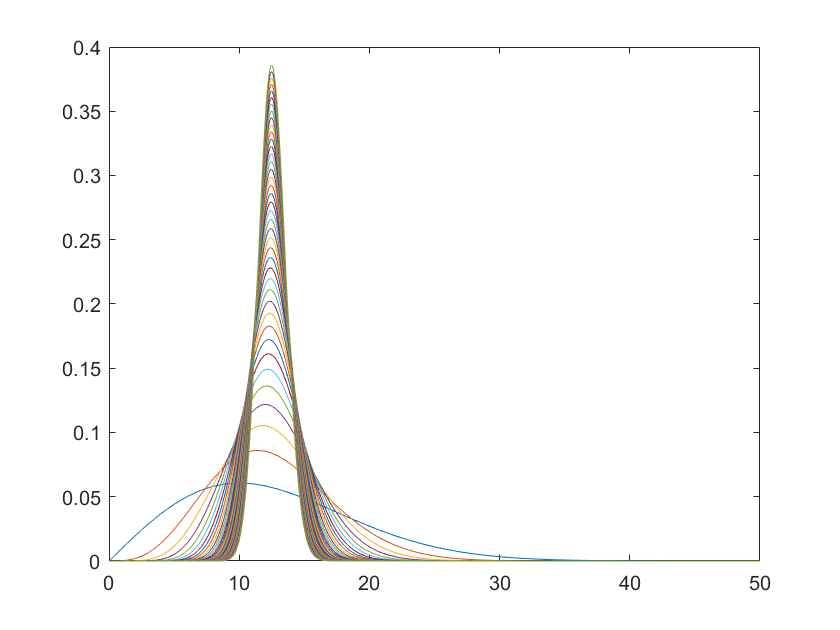

for k = 2:40 % needs to be very high (1000+) to bring edges in on log plot
    pdfnew = conv(pdfray,pdfold);
    plot((0:(length(pdfnew)-1))/k,pdfnew*k);
    pdfold = pdfnew;
end
hold off;

B) The sides pull in and we settle about a mean. The Rayleigh distribution appears to also be approaching a Gaussian. How many intervals does it require?

% testing against a gaussian
x1 = (0:(numel(pdfnew)-1))/k;
sum(pdfnew) % this might be an issue!

ans = 1.0000

mean = dot(x1,(pdfnew)*k/k) % sum of products of x and prob(x)

mean = 12.5435

% if pdfnew is normalized pdfnew/k, then prob is this times the step k to
% get back pdfnew
vari = dot((x1 - mean).^2,(pdfnew)*k/k) % calculating variance

vari = 1.0705

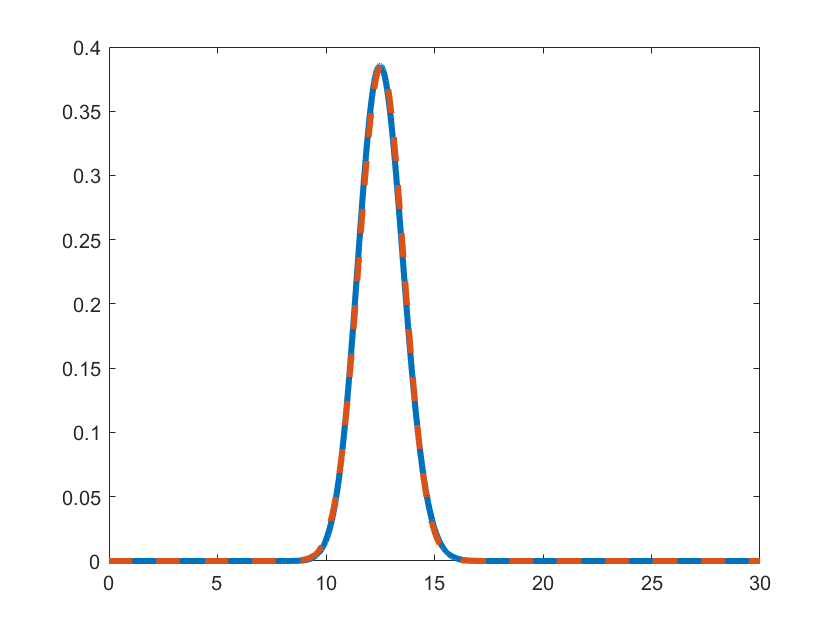

% making the Gaussian distribution with these values
gaussdist = makedist("Normal","mu",mean,"sigma",sqrt(vari));
y3 = pdf(gaussdist,x1);
plot(x1,pdfnew*k,"LineWidth",3); % original plot
hold on;
plot(x1,y3,"LineStyle","--","LineWidth",3); % Gaussian plot
xlim([0,30]);
hold off;

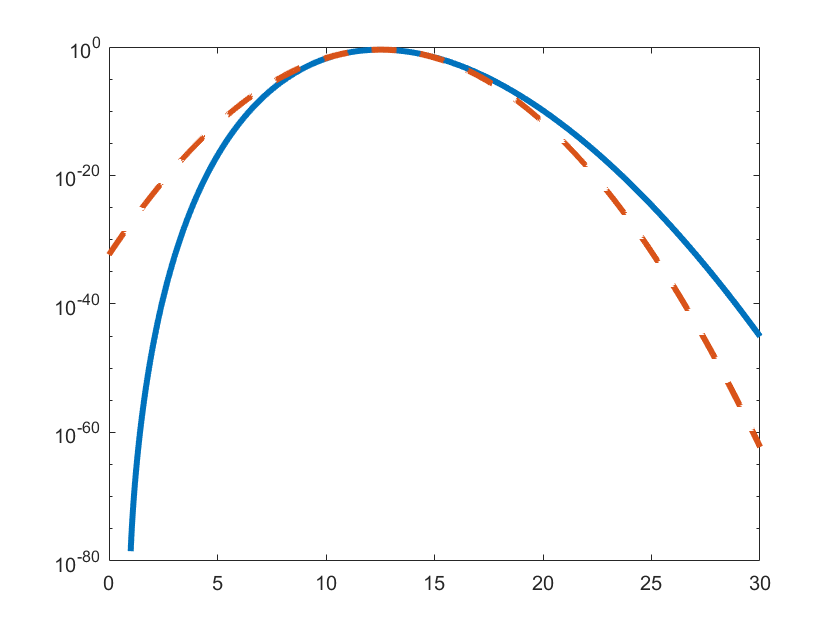

plot(x1,pdfnew*k,"LineWidth",3);
hold on;
plot(x1,y3,"LineStyle","--","LineWidth",3);
xlim([0,30]);
set(gca,'YScale','log');

Graphing a Gaussian with the same mean and standard deviation shows that they are close. Closer with more convolutions. To approach a Gaussian it needs about 50 to overlap sufficiently with the standard plot, however the log plot needs much more to be convinced as increasing beyond this shows little improvement.

## Problem 3

A)

clc; clear; close all;
X = makedist("Normal","mu",10,"sigma",2); % background Gaussian distribution
Y = 23.1; % signal strength, floating point
prob = cdf(X,Y,'upper');
sigma = abs(norminv(prob))

sigma = 6.5500

Yes, this is more than 5-sigma. I can claim a discovery!

B)

The probability distribution of my background will be the single pixel background scaled by a trial factor. In this case we have to look in 10,000 places. We scale the PDF with this number and reintegrate this distribution. (The probability that the signal-free background will produce something that looks as much or more signal-like is now also just the total sum of the probability for each pixel, or the product of the individual probability with 10,000.)

C)

tenkprob = 10000*prob

tenkprob = 2.8769e-07

tenksigma = abs(norminv(tenkprob))

tenksigma = 4.9993

Surprisingly, the significance is now just a hair under 5 sigma.

## Problem 4

clc; clear; close all;
X = makedist("Normal","mu",10,"sigma",2);
trials = 10000;

A)

fivesigma = normcdf(5,'upper')

fivesigma = 2.8665e-07

det1 = icdf(X,1-fivesigma)

det1 = 20.0000

Need a signal of 20.

B)

det2 = icdf(X,1-fivesigma/trials)

det2 = 23.1011

We now need a signal of 23.1011.

C)

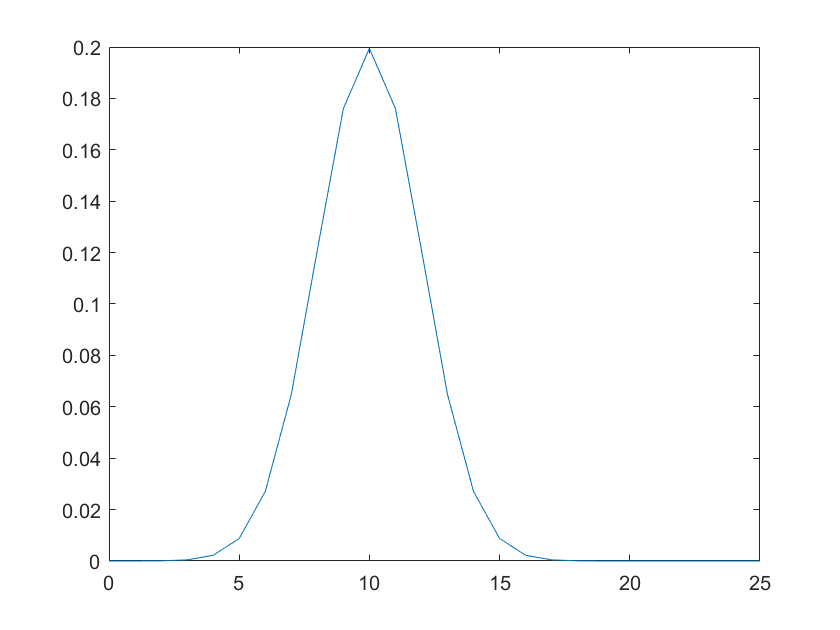

plot(0:100,pdf(X,0:100));
xlim([0,25]);

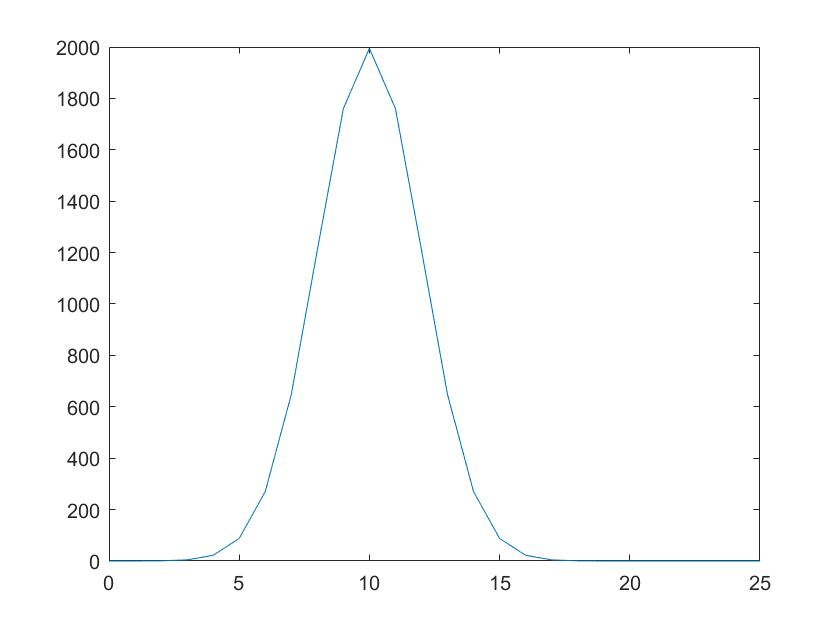

plot(0:100,pdf(X,0:100)*trials);
xlim([0,25]);

The signal only needs to be a little over 3 units brighter. The sensitivity penalty for the trials factor is so low because the probability falls off so rapidly that you don't need to move very far out to make up for it.

D) Significantly changing the trials factor.

% orders of magnitude 10^x
values = [];
for x = -4:5
    values = [values,icdf(X,1-fivesigma/(trials*10^x))];
end
values

values =    20.0000   20.8539   21.6487   22.3952   23.1011   23.7723   24.4134   25.0283   25.6176   26.1531


diff(values)

ans =     0.8539    0.7949    0.7465    0.7059    0.6712    0.6411    0.6149    0.5893    0.5355


Effect on my 5-sigma sensitivity threshold is smaller for each higher order of magnitude.

Extra credit:

For a differently shaped distribution, the sensitivity penalty will be affected by how quickly that distribution falls off at larger signals. Longer tails, such as in an exponential distribution, will feature a higher sensitivity penalty than ones with short tails like the normal distribution.